# Sample 13-2

## 辞書学習

再構成独立成分分析

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Dictionary learning

Reconstruction ICA

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

clear 
close all
import msip.download_img
msip.download_img

lena.png already exists in ./data/
baboon.png already exists in ./data/
goldhill.png already exists in ./data/
barbara.png already exists in ./data/


### パラメータ設定

(Parameter settings)

- ブロックサイズ (Block size)

- 冗長率 (Redundancy ratio)

- 繰返し回数 (Number of iterations)

- 正則化パラメータ (Regularization parameter)

% Block size
szBlk = [ 8 8 ];
nDims = prod(szBlk);

% Redundancy ratio
redundancyRatio = 1.5;

% Number of iterations
nIters = 1000;

% Regularization parameter
alpha = 0.5;

## 画像の読込

(Read image)

- 
$$\mathbf{u}\in\mathbb{R}^{N}$$


u = rgb2gray(im2double(imread('./data/lena.png')));

## 再構成独立成分分析

(Reconstruction ICA)

#### 問題設定 (Problem setting):

        
$$\widehat{\mathbf{\Phi}}=\arg \max _{\mathbf{\Phi}} \frac{1}{2S}\sum_{n=1}^S\|\mathbf{y}_n-\mathbf{\Phi}\mathbf{\Phi}^T\mathbf{y}_n\|_2^2+\frac{\alpha}{S}\sum_{n=1}^{S}\rho(\mathbf{\Phi}^T\mathbf{y}_n)
$$


            
$$=\arg \max _{\mathbf{\Phi}} \frac{(2\alpha)^{-1}}{S}\sum_{n=1}^S\|\mathbf{y}_n-\mathbf{\Phi}\mathbf{\Phi}^T\mathbf{y}_n\|_2^2+\frac{1}{S}\sum_{n=1}^{S}\rho(\mathbf{\Phi}^T\mathbf{y}_n)$$


ただし，  $\{\mathbf{y}_n\}_n\subset\mathbb{R}^{M}$,  $\mathbf{\Phi}=(\mathbf{\phi}_1,\mathbf{\phi}_2,\cdots,\mathbf{\phi}_P)\in\mathbb{R}^{M\times P}$, $M\geq P$ である．(where，$\{\mathbf{y}_n\}_n\subset\mathbb{R}^{M}$ and  $\mathbf{\Phi}=(\mathbf{\phi}_1,\mathbf{\phi}_2,\cdots,\mathbf{\phi}_P)\in\mathbb{R}^{M\times P}$, $M\geq P$.)

#### 参考文献 (Reference):

Le, Quoc V., Alexandre Karpenko, Jiquan Ngiam, and Andrew Y. Ng. “ICA with Reconstruction Cost for Efficient Overcomplete Feature Learning.” Advances in Neural Information Processing Systems. Vol. 24, 2011, pp. 1017–1025. https://papers.nips.cc/paper/4467-ica-with-reconstruction-cost-for-efficient-overcomplete-feature-learning.pdf. 

画像 $\mathbf{u}$からのデータ行列 $\mathbf{Y}$ の生成 (Generation of data matrix  $\mathbf{Y}$  of image $\mathbf{u}$)

Y = im2col(u,szBlk,'distinct');

コントラスト関数の例 (Example of contrast function)

        
$$\rho(\mathbf{\Phi}^T\mathbf{y})\colon = \frac{1}{2}\sum_{p=1}^{P}\log\circ\cosh(2\mathbf{\phi}_p^T\mathbf{y})$$


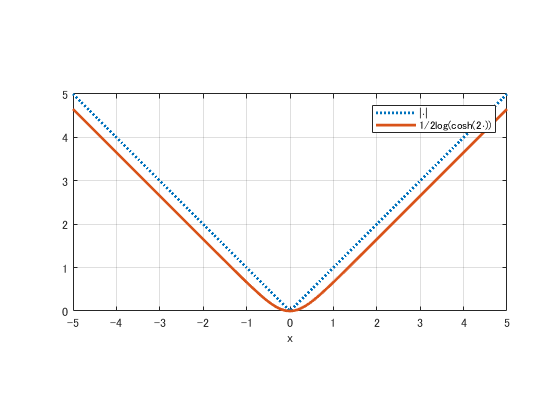

figure(1)
fplot(@(x) abs(x),[-5 5],':','LineWidth',2,'DisplayName','|\cdot|')
hold on
fplot(@(x) log(cosh(2*x))/2,[-5 5],'-','LineWidth',2,'DisplayName','1/2log(cosh(2\cdot))')
xlabel('x')
legend
grid on
axis equal
hold off

要素画像の数 (Number of atomic images)

nAtoms = ceil(redundancyRatio*nDims);

辞書 $\mathbf{\Phi}$の初期化 (Initializatio of dictionary $\mathbf{\Phi}$)

- 二変量離散コサイン変換(Bivariate DCT)

- ランダム (random)

Phi = randn(nDims,nAtoms);
Phi = Phi/norm(Phi,'fro');
for iAtom = 1:nDims
    delta = zeros(szBlk);
    delta(iAtom) = 1;
    Phi(:,iAtom) = reshape(idct2(delta),nDims,1);
end

要素ベクトルを要素画像に変換 (Reshape the atoms into atomic images)

atomicImages = zeros(szBlk(1),szBlk(2),nAtoms);
for iAtom = 1:nAtoms
    atomicImages(:,:,iAtom) = reshape(Phi(:,iAtom),szBlk(1),szBlk(2));
end

### 画像表示

(Image show)

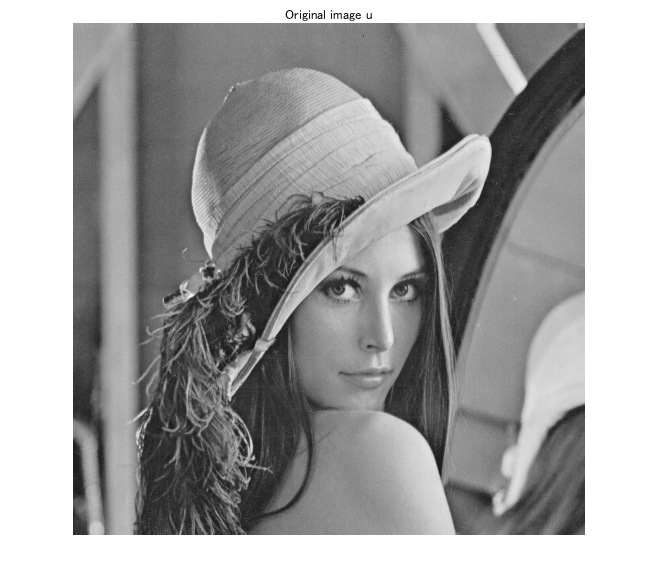

figure(2)
imshow(u);
title('Original image u')

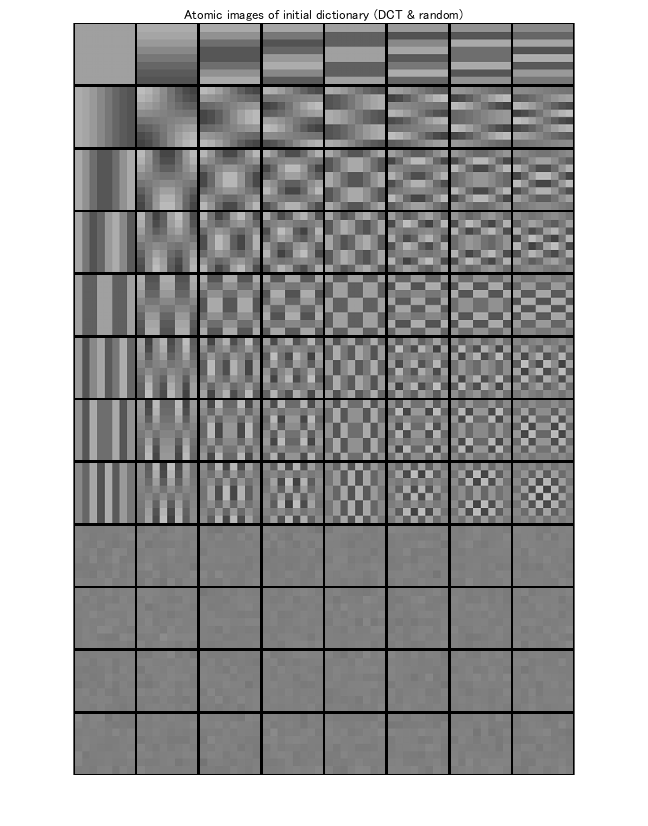

figure(3)
montage(imresize(atomicImages,8,'nearest')+.5,'BorderSize',[2 2],'Size',[ceil(nAtoms/8) 8])
title('Atomic images of initial dictionary (DCT & random)')

#### 再構成 ICA オブジェクトの作成 (Creation of reconstructio ICA object)

model = rica(Y.',nAtoms,...
    'IterationLimit',nIters,...
    'ContrastFcn','logcosh',...
    'InitialTransformWeight',Phi,...
    'Lambda',1/(2*alpha));

コスト評価のグラフ (Graph of cost variation)

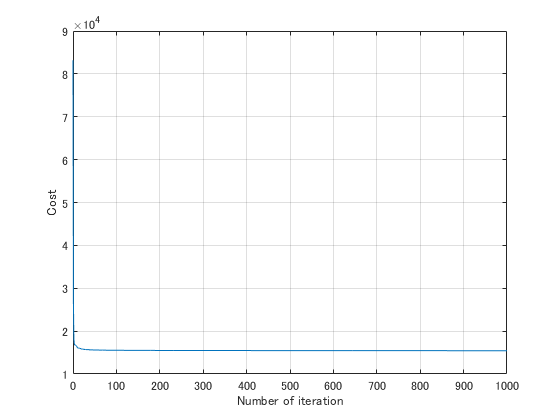

info = model.FitInfo;
figure(4)
plot(info.Iteration,info.Objective)
xlabel('Number of iteration')
ylabel('Cost')
grid on

要素ベクトルを要素画像に変換 (Reshape the atoms into atomic images)

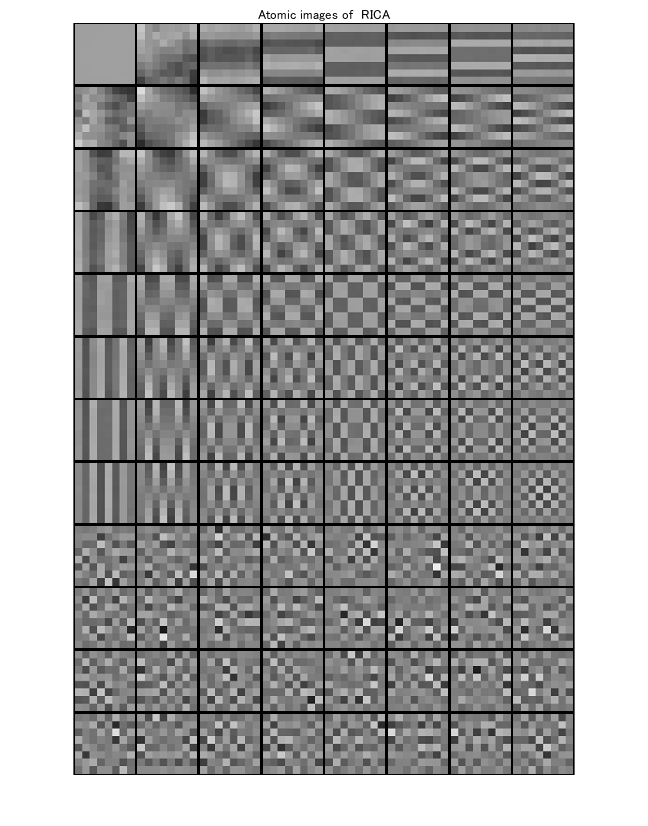

Phi = model.TransformWeights;
atomicImages = zeros(szBlk(1),szBlk(2),nAtoms);
for iAtom = 1:nAtoms
    atomicImages(:,:,iAtom) = reshape(Phi(:,iAtom),szBlk(1),szBlk(2));
end
figure(5)
montage(imresize(atomicImages,8,'nearest')+.5,'BorderSize',[2 2],'Size',[ceil(nAtoms/8) 8])
title('Atomic images of　RICA')

© Copyright, Shogo MURAMATSU, All rights reserved.